# **Conway's Game Of Life - Instrucciones**

**Juan Uriel Legaria Peña**

**Inteligencia Artificial**

**Maestria en Ciencia e Ingeniería de la Computación**

La implementación realizada consta de 3 partes importantes 

*DemoConfigs: *Genera patrones iniciales icónicos del juego sobre una rejilla  de ancho y largo dados. Hasta el momento la libreria disponible consta de 

- Patrones estáticos: Block y Beehive.

- Osciladores: Blinker y Pulsar

- Naves espaciales: Glider y Light-Weight spaceship. 

*ConwaysGameOfLife: *Es como tal el autómata, para inicializarlo se requiere pasar como argumente a su constructior una rejilla inicial a evolucionar.

*ConwaysRenderer: *Es una clase que genera animaciones de la evolución del autómata, su constructor requiere un objeto de tipo ConwaysGameOfLife para su inicialización. La animación como tal se realiza usando el método render Evolution, cuyo argumento recibe el número de pasos que deseamos que tome la evolución. Dicho método regresa un arreglo de cuadros que podemos usar para exportar una película, o visualizarlo por medio del método movie(frames) que ofrece MATLAB. En mi caso sin embargo la película por algun motivo se visualiza cortada con este método, por lo cual encontré mas apropiado exportarlos. 

## Ejemplos 

### Block (Patrón estático)

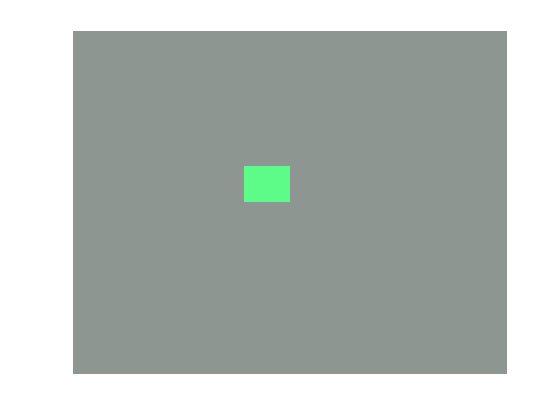

%Inicializamos el generador de configuraciones predefinidas iniciales
configGenerator = DemoConfigs();
%El tipo de demo que queremos para este ejemplo es un bloque
demoType = DemoType.BLOCK;
%Nuestro mundo será de 20 x 20 para este caso
gridWidth = 20;
gridHeight = 20;
%Imprimimos el patrón demostrativo inicial en una rejilla con las
%dimensiones deseadas
initialGrid = configGenerator.getDemoConfig(demoType,gridWidth,gridHeight);
%Inicializamos el autómata con la rejilla inicial
game = ConwaysGameOfLife(initialGrid);
%Creamos un renderizador para obtener los frames de la película de
%evolución del autómata
renderer = ConwaysRenderer(game);
steps = 5;
frames = renderer.renderEvolution(steps);

%Se exporta el video 
v = VideoWriter("block",'MPEG-4');
fps = 1;
v.FrameRate = fps;
open(v)
writeVideo(v,frames)
close(v)

### Beehive (Patrón estático)

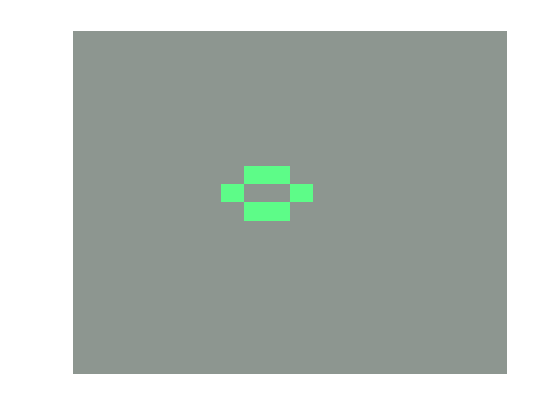

%Inicializamos el generador de configuraciones predefinidas iniciales
configGenerator = DemoConfigs();
%El tipo de demo que queremos para este ejemplo es un beehive
demoType = DemoType.BEEHIVE;
%Nuestro mundo será de 20 x 20 para este caso
gridWidth = 20;
gridHeight = 20;
%Imprimimos el patrón demostrativo inicial en una rejilla con las
%dimensiones deseadas
initialGrid = configGenerator.getDemoConfig(demoType,gridWidth,gridHeight);
%Inicializamos el autómata con la rejilla inicial
game = ConwaysGameOfLife(initialGrid);
%Creamos un renderizador para obtener los frames de la película de
%evolución del autómata
renderer = ConwaysRenderer(game);
steps = 5;
frames = renderer.renderEvolution(steps);

%Exportación del video
v = VideoWriter("beehive",'MPEG-4');
fps = 1;
v.FrameRate = fps;
open(v)
writeVideo(v,frames)
close(v)

### Blinker (Oscilador)

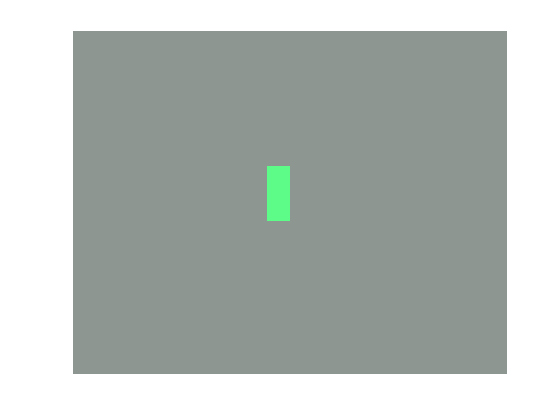

%Inicializamos el generador de configuraciones predefinidas iniciales
configGenerator = DemoConfigs();
%El tipo de demo que queremos para este ejemplo es un blinker
demoType = DemoType.BLINKER;
%Nuestro mundo será de 20 x 20 para este caso
gridWidth = 20;
gridHeight = 20;
%Imprimimos el patrón demostrativo inicial en una rejilla con las
%dimensiones deseadas
initialGrid = configGenerator.getDemoConfig(demoType,gridWidth,gridHeight);
%Inicializamos el autómata con la rejilla inicial
game = ConwaysGameOfLife(initialGrid);
%Creamos un renderizador para obtener los frames de la película de
%evolución del autómata
renderer = ConwaysRenderer(game);
steps = 5;
frames = renderer.renderEvolution(steps);

%Exportación del video
v = VideoWriter("blinker",'MPEG-4');
fps = 1;
v.FrameRate = fps;
open(v)
writeVideo(v,frames)
close(v)

### Pulsar (Oscilador)

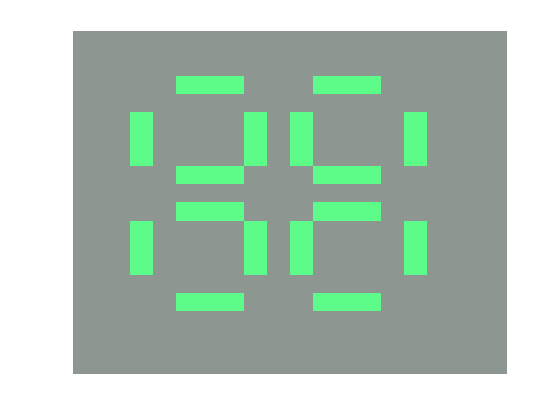

%Inicializamos el generador de configuraciones predefinidas iniciales
configGenerator = DemoConfigs();
%El tipo de demo que queremos para este ejemplo es un pulsar
demoType = DemoType.PULSAR;
%Nuestro mundo será de 20 x 20 para este caso
gridWidth = 20;
gridHeight = 20;
%Imprimimos el patrón demostrativo inicial en una rejilla con las
%dimensiones deseadas
initialGrid = configGenerator.getDemoConfig(demoType,gridWidth,gridHeight);
%Inicializamos el autómata con la rejilla inicial
game = ConwaysGameOfLife(initialGrid);
%Creamos un renderizador para obtener los frames de la película de
%evolución del autómata
renderer = ConwaysRenderer(game);
steps = 10;
frames = renderer.renderEvolution(steps);

%Exportación del video
v = VideoWriter("pulsar",'MPEG-4');
fps = 1;
v.FrameRate = fps;
open(v)
writeVideo(v,frames)
close(v)

### Glider (Nave espacial)

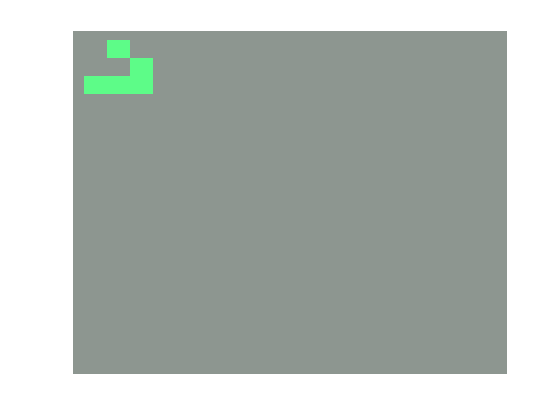

%Inicializamos el generador de configuraciones predefinidas iniciales
configGenerator = DemoConfigs();
%El tipo de demo que queremos para este ejemplo es un glider
demoType = DemoType.GLIDER;
%Nuestro mundo será de 20 x 20 para este caso
gridWidth = 20;
gridHeight = 20;
%Imprimimos el patrón demostrativo inicial en una rejilla con las
%dimensiones deseadas
initialGrid = configGenerator.getDemoConfig(demoType,gridWidth,gridHeight);
%Inicializamos el autómata con la rejilla inicial
game = ConwaysGameOfLife(initialGrid);
%Creamos un renderizador para obtener los frames de la película de
%evolución del autómata
renderer = ConwaysRenderer(game);
steps = 100;
frames = renderer.renderEvolution(steps);

%Exportación del video
v = VideoWriter("glider",'MPEG-4');
fps = 3;
v.FrameRate = fps;
open(v)
writeVideo(v,frames)
close(v)

### Nave espacial ligera (Nave espacial)

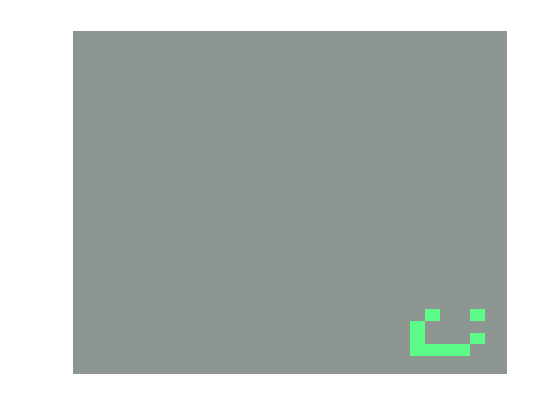

%Inicializamos el generador de configuraciones predefinidas iniciales
configGenerator = DemoConfigs();
%El tipo de demo que queremos para este ejemplo es un light spaceship
demoType = DemoType.LIGHT_SPACESHIP;
%Nuestro mundo será de 30 x 30 para este caso
gridWidth = 30;
gridHeight = 30;
%Imprimimos el patrón demostrativo inicial en una rejilla con las
%dimensiones deseadas
initialGrid = configGenerator.getDemoConfig(demoType,gridWidth,gridHeight);
%Inicializamos el autómata con la rejilla inicial
game = ConwaysGameOfLife(initialGrid);
%Creamos un renderizador para obtener los frames de la película de
%evolución del autómata
renderer = ConwaysRenderer(game);
steps = 100;
frames = renderer.renderEvolution(steps);

%Exportación del video
v = VideoWriter("light_spaceship",'MPEG-4');
fps = 3;
v.FrameRate = fps;
open(v)
writeVideo(v,frames)
close(v)

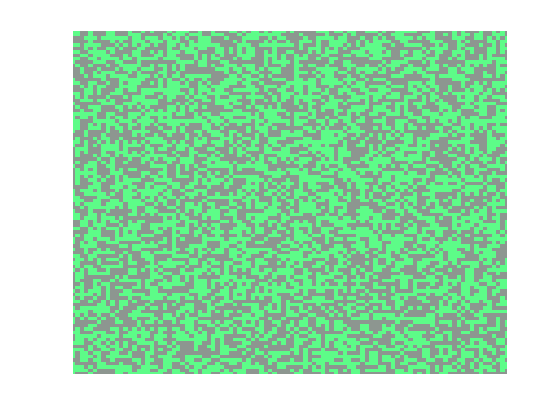

%Inicializamos el generador de configuraciones predefinidas iniciales
configGenerator = DemoConfigs();
%El tipo de demo que queremos para este ejemplo es un light spaceship
demoType = DemoType.RANDOM;
%Nuestro mundo será de 30 x 30 para este caso
gridWidth = 100;
gridHeight = 100;
%Imprimimos el patrón demostrativo inicial en una rejilla con las
%dimensiones deseadas
initialGrid = configGenerator.getDemoConfig(demoType,gridWidth,gridHeight);
%Inicializamos el autómata con la rejilla inicial
game = ConwaysGameOfLife(initialGrid);
%Creamos un renderizador para obtener los frames de la película de
%evolución del autómata
renderer = ConwaysRenderer(game);
steps = 100;
frames = renderer.renderEvolution(steps);


%Exportación del video
v = VideoWriter("random",'MPEG-4');
fps = 3;
v.FrameRate = fps;
open(v)
writeVideo(v,frames)
close(v)